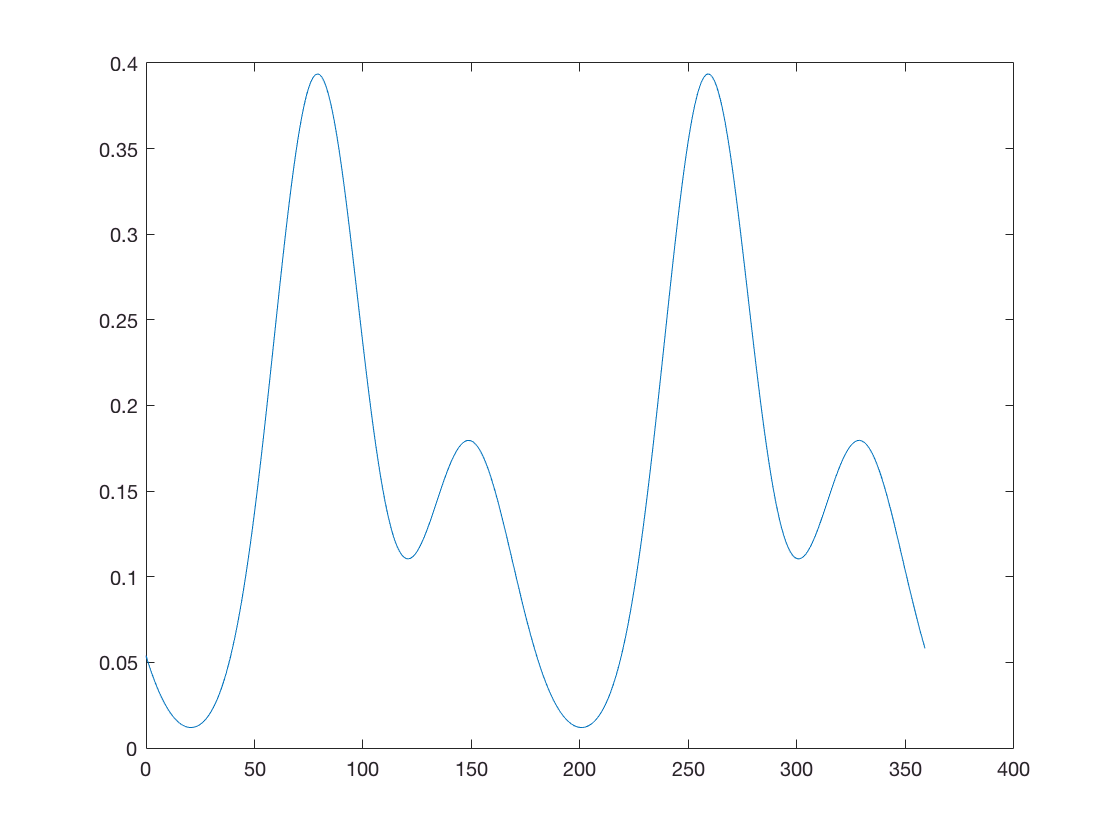

warning off
clear all
clc
addpath(genpath('../..'));

theta_full = 0:pi/180:2*pi-pi/180;
data_raw1 = [27 33 40 48 58 70 84 101 121 144 171 203 240 283 333 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22 27 33 40 48 58 70 84 101 121 144 171 203 240 283 334 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22];
data_raw2 = data_raw1;
data_raw2 = circshift(data_raw2',70)'/2.2;
data_raw = data_raw1 + data_raw2;


data_point_ = data_point;

data_point_.intensity_data = data_raw;
data_point_ = data_point_.Normalize;

plot(theta_full*180/pi, data_point_.odd);

data_point_ = data_point_.GenerateFourier(14);

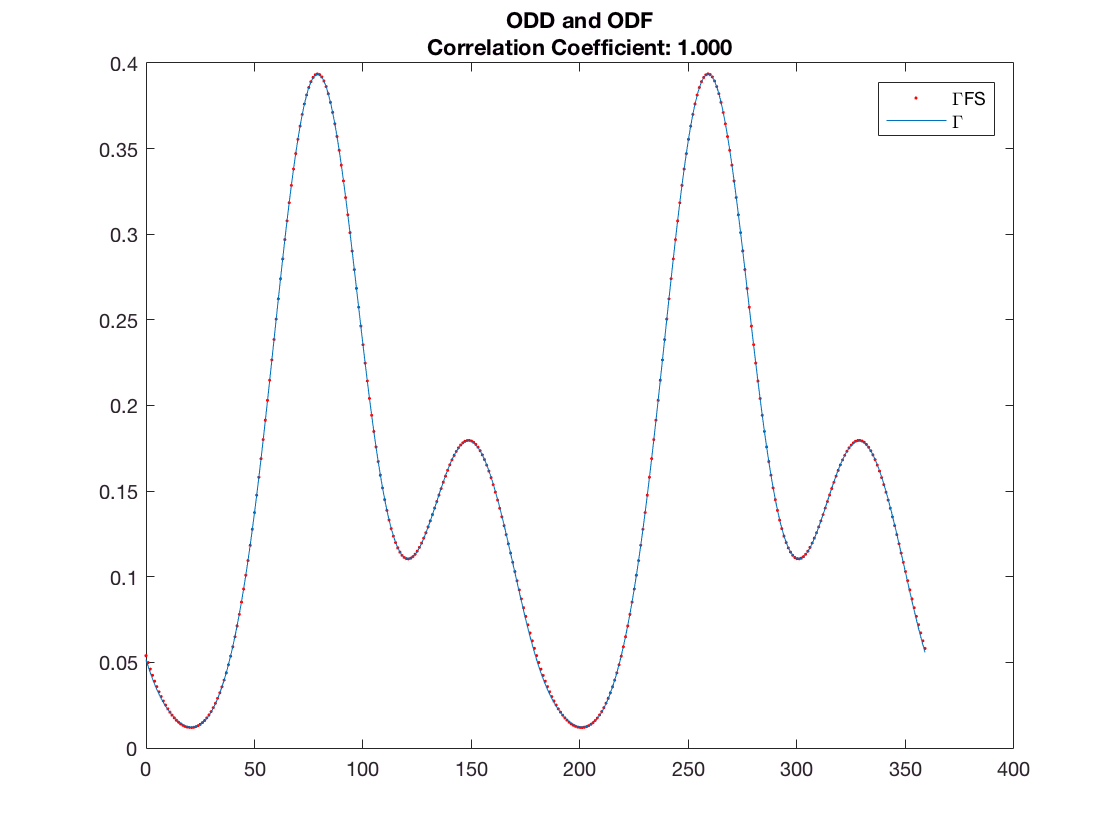

plot(theta_full*180/pi, data_point_.odd, 'r.', theta_full*180/pi, data_point_.odf);
title(sprintf('ODD and ODF\nCorrelation Coefficient: %0.3f', data_point_.corr_coeff));
legend('\GammaFS', '\Gamma');

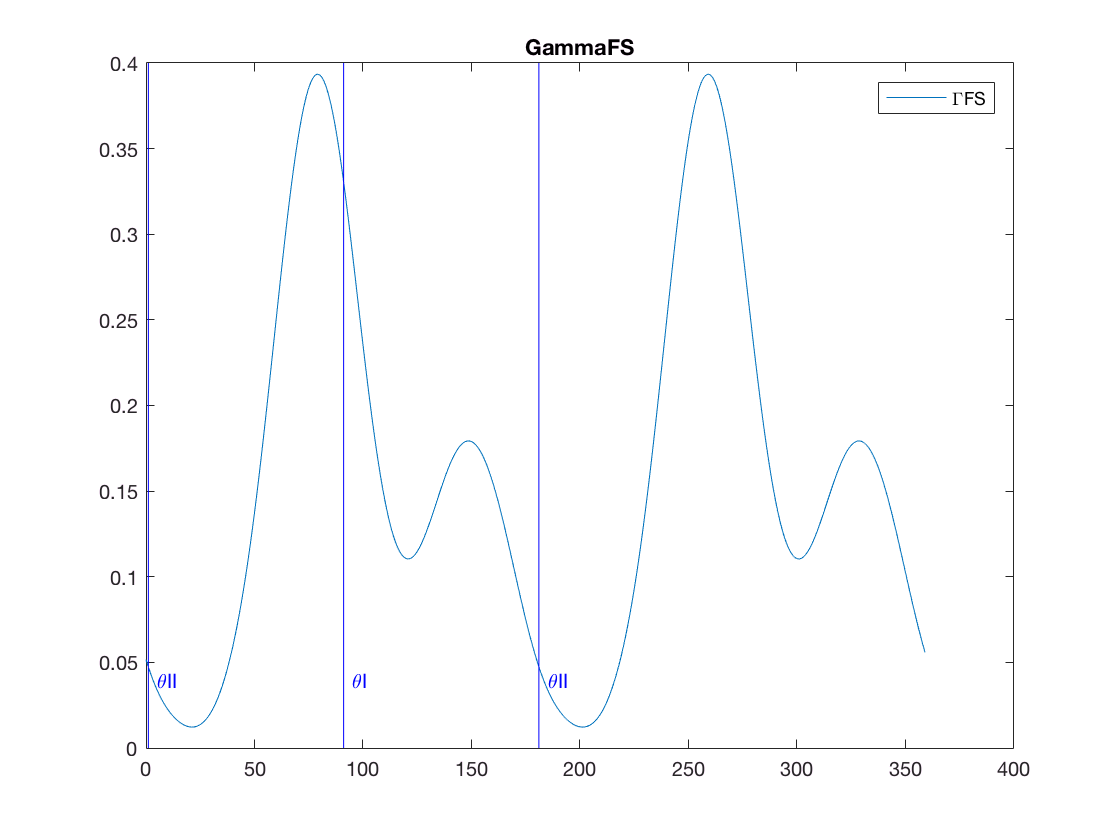

plot(theta_full*180/pi, data_point_.odf);
[thetaI, thetaII] = data_point_.ComputeSymAngles();
title(sprintf('GammaFS', data_point_.corr_coeff));
vline(thetaI*180/pi + 180, 'b', '\thetaI');
vline(thetaII*180/pi, 'b', '\thetaII'); vline(thetaII*180/pi + 180, 'b', '\thetaII');
legend('\GammaFS');

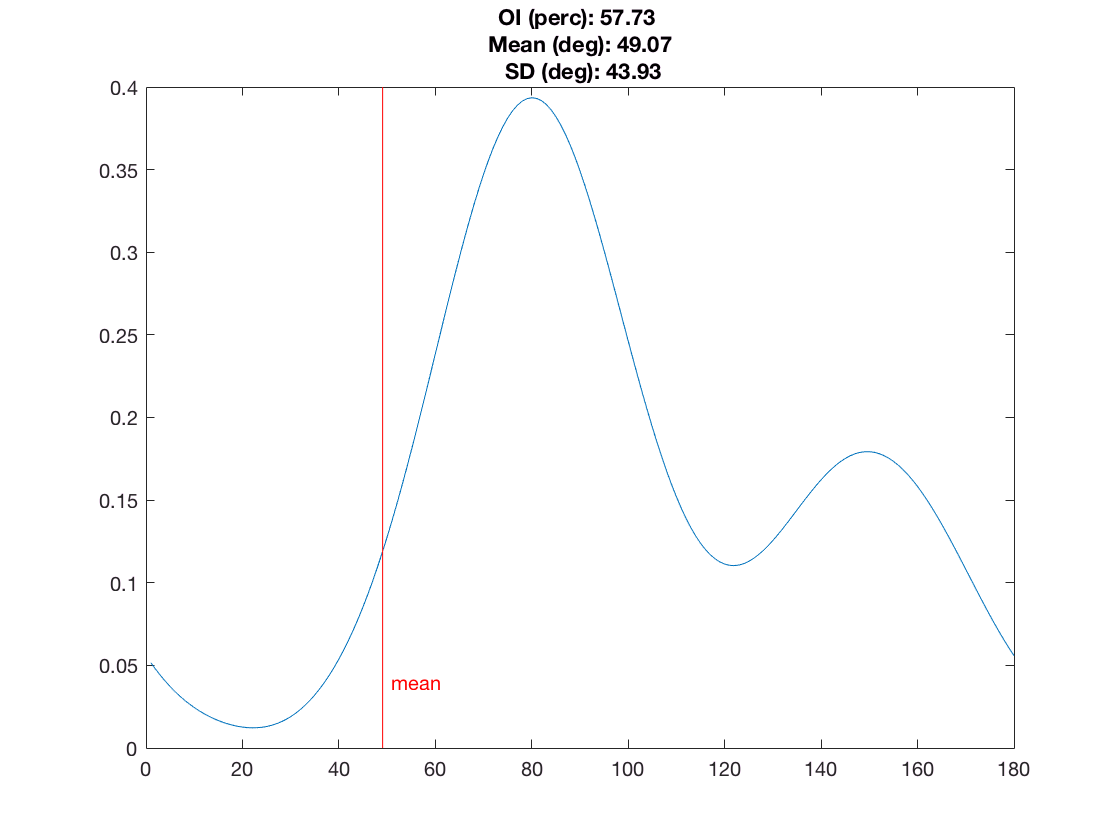

[pi_half_odf, pi_half_odf_range] = data_point_.GetODFPiSegment();
interval = pi/720;
theta = thetaII:interval:thetaII + pi;
odf_FS_fit = evalFourierRad(data_point_.an, data_point_.bn, 2,  theta);

mean = compute_mean(pi_half_odf, pi_half_odf_range);
[oi, sd] = compute_orientation_index(mean, pi_half_odf, pi_half_odf_range);
data_point_.mean_odf = mean*180/pi;
data_point_.oi_odf = oi;
data_point_.sd_odf = sd;

plot(pi_half_odf_range*180/pi, pi_half_odf);

title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean*180/pi, sd*180/pi));
vline(mean*180/pi, 'r', 'mean');

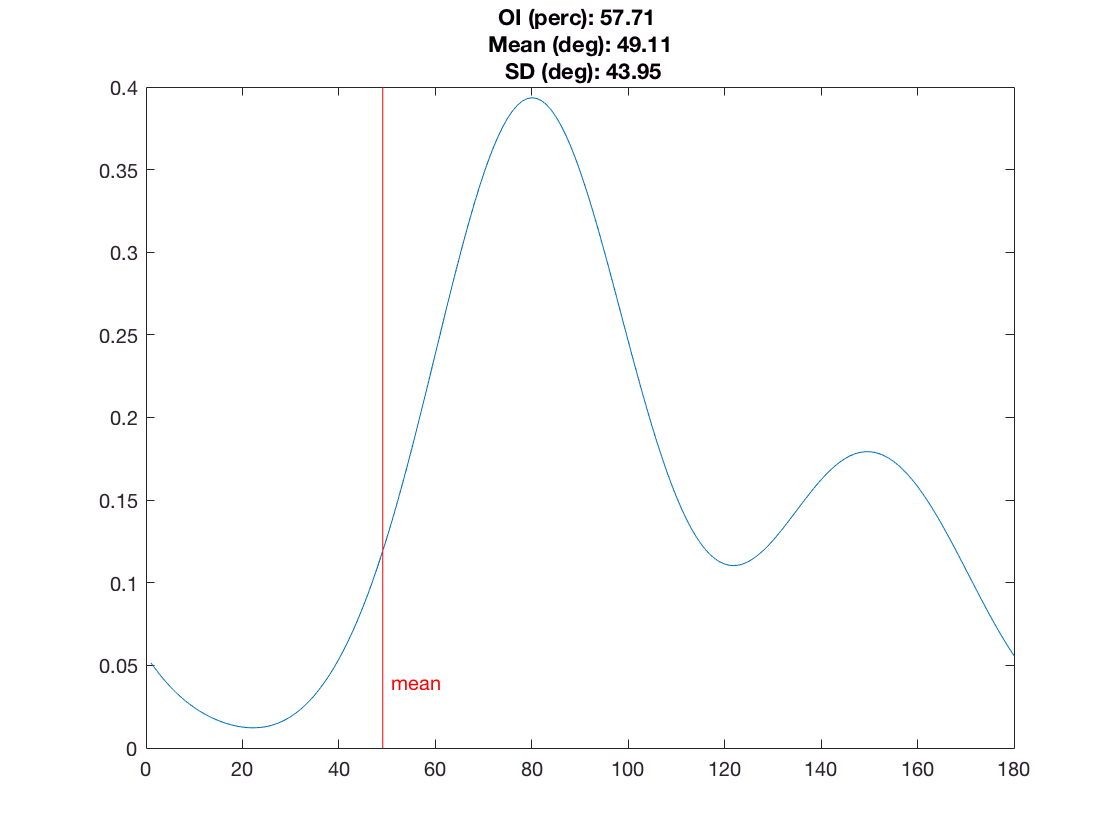

[pi_half_odd, pi_half_odd_range] = data_point_.GetODDPiSegment();

mean = compute_mean(pi_half_odd, pi_half_odd_range);
[oi, sd] = compute_orientation_index(mean, pi_half_odd, pi_half_odd_range);
data_point_.mean_odd = mean*180/pi;
data_point_.oi_odd = oi;
data_point_.sd_odd = sd;

plot(pi_half_odd_range*180/pi, pi_half_odf);

title(sprintf('OI (perc): %.2f \n Mean (deg): %.2f \n SD (deg): %.2f', oi, mean*180/pi, sd*180/pi));
vline(mean*180/pi, 'r', 'mean');